%Final k3 spline
%for k = 3
P1 = [0,100];
P2 = [0, 100];
P3 = [0, 100];
P4 = [50, 0];
P5 = [100, 100];
P6 = [100, 100];
%found reason for open unform error - having multiple knots at the same
%value throughs the following if statement results to NaN
%therefore 'identicle' not vectors need to be one step away from each
%other, to allow the simulation time to process Nxk1 values
%next issue -> program successfully passes through P1 however does not
%reach P6 -> could be due to the cut off time for the curves validity /\(30/10/2023, 12:52)

%26/02/2024 more reasonable knot(0->60 instead of 18->60)
t1 = 0;
t2 = 0.01;
t3 = 0.02;
t4 = 24;
t5 = 30;
t6 = 36;
t7 = 42;
t8 = 59.8;
t9 = 59.9;
t10 = 60;

validtmin = t3;
validtmax = t7;
tmin = 0;
tmax = 60;
step = 0.01;

stackx = [];
stacky = [];

for t = tmin:step:tmax
    if (t1<=t)
        if (t<t2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (t2<=t)
        if (t<t3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (t3<=t)
        if (t<t4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (t4<=t)
        if (t<t5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (t5<=t)
        if (t<t6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (t6<=t)
        if (t<t7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (t7<=t)
        if (t<t8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    if (t8<=t)
        if (t<t9)
            N8k1 = 1;
        else
            N8k1 = 0;
        end
    else
        N8k1 = 0;
    end
    if (t9<=t)
        if (t<t10)
            N9k1 = 1;
        else
            N9k1 = 0;
        end
    else
        N9k1 = 0;
    end
    N1k2 = ((t-t1)/(t2-t1))*N1k1 + ((t3-t)/(t3-t2))*N2k1;
    N2k2 = ((t-t2)/(t3-t2))*N2k1 + ((t4-t)/(t4-t3))*N3k1;
    N3k2 = ((t-t3)/(t4-t3))*N3k1 + ((t5-t)/(t5-t4))*N4k1;
    N4k2 = ((t-t4)/(t5-t4))*N4k1 + ((t6-t)/(t6-t5))*N5k1;
    N5k2 = ((t-t5)/(t6-t5))*N5k1 + ((t7-t)/(t7-t6))*N6k1;
    N6k2 = ((t-t6)/(t7-t6))*N6k1 + ((t8-t)/(t8-t7))*N7k1;
    N7k2 = ((t-t7)/(t8-t7))*N7k1 + ((t9-t)/(t9-t7))*N8k1;
    N8k2 = ((t-t8)/(t9-t8))*N8k1 + ((t10-t)/(t10-t7))*N9k1;

    N1k3 = ((t-t1)/(t3-t1))*N1k2 + ((t4-t)/(t4-t2))*N2k2;
    N2k3 = ((t-t2)/(t4-t2))*N2k2 + ((t5-t)/(t5-t3))*N3k2;
    N3k3 = ((t-t3)/(t5-t3))*N3k2 + ((t6-t)/(t6-t4))*N4k2;
    N4k3 = ((t-t4)/(t6-t4))*N4k2 + ((t7-t)/(t7-t5))*N5k2;
    N5k3 = ((t-t5)/(t7-t5))*N5k2 + ((t8-t)/(t8-t6))*N6k2;
    N6k3 = ((t-t6)/(t8-t6))*N6k2 + ((t9-t)/(t9-t7))*N7k2;
    N7k3 = ((t-t7)/(t9-t7))*N7k2 + ((t10-t)/(t10-t8))*N8k2;

    SumNPx = N1k3*P1(1,1) + N2k3*P2(1,1) + N3k3*P3(1,1) + N4k3*P4(1,1) + N5k3*P5(1,1) + N6k3*P6(1,1);
    SumNPy = N1k3*P1(1,2) + N2k3*P2(1,2) + N3k3*P3(1,2) + N4k3*P4(1,2) + N5k3*P5(1,2) + N6k3*P6(1,2);

    if t >= validtmin
        if t<=validtmax
            stackx = [stackx; SumNPx];
            stacky = [stacky; SumNPy];
        end
    end
end

CP = [P1; P2; P3; P4; P5; P6]

CP =      0   100
     0   100
     0   100
    50     0
   100   100
   100   100


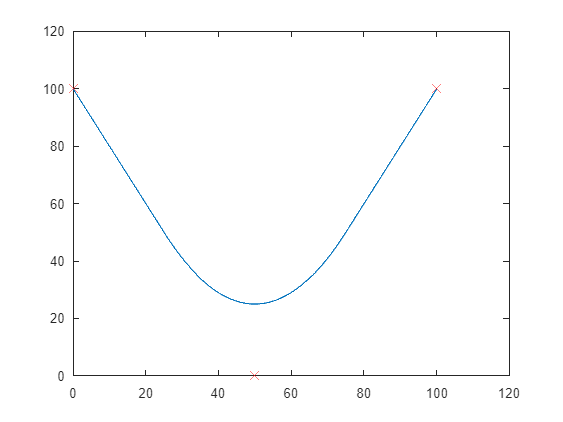

CPx = [P1(1,1), P2(1,1), P3(1,1), P4(1,1), P5(1,1), P6(1,1)];
CPy = [P1(1,2), P2(1,2), P3(1,2), P4(1,2), P5(1,2), P6(1,2)];
plot(stackx, stacky)
hold on
scatter(CPx, CPy, 100, "red", "X")
hold off

knotV = [t1, t2, t3, t4, t5, t6, t7, t8, t9, t10]

knotV =          0    0.0100    0.0200   24.0000   30.0000   36.0000   42.0000   59.8000   59.9000   60.0000
